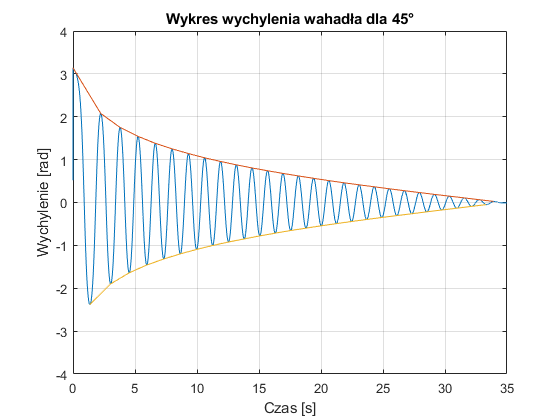

close all;

start = 162;
time = P1_ExpData.time(start:end)-start*0.01;
arc = P1_ExpData.signals(4).values(start:end);
plot(time, arc)
grid on;
hold on;
title('Wykres wychylenia wahadła dla 45°')
xlabel('Czas [s]')
ylabel('Wychylenie [rad]')
axis([0 35 -4 4])
[peaks, locs] = findpeaks(arc);
plot(time(locs), peaks)
[bot_peaks, bot_locs] = findpeaks(-arc);
plot(time(bot_locs), -bot_peaks)

bot_l = bot_locs(3:end);
bot_p = bot_peaks(3:end);
max(arc)

ans = 3.1416